## Synthesis of controller with wights

This script test tests the controller synthesised including the information of $W_\Delta$ 

### Initilization

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Singular values when gamma is a variable

The first synthesized controller is found when minimizing gamma. 

param = control.DesignProcedureWeight(param,0,0);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0005    0.0006    0.0006    0.0126    0.0711    0.0717    0.0719    0.0789    0.4301    0.4301    0.4301    0.4301    0.9880    1.6935    1.7215    1.7231


Gamma is found to be:


ans = 0.2282

Eigenvalues of the decoupled systems are all negative 


ans =    -4.1614   -0.9900   -0.1120  -28.4368   -4.0286   -0.0231  -25.4541   -3.9895   -0.0231  -24.6892   -3.9893   -0.0225


Eigenvalues of the coupled systems are all negative 


ans =   -65.0654  -60.4732  -46.9652   -2.0245   -4.5070   -4.0299   -3.9907   -3.9911   -0.1073   -0.0225   -0.0231   -0.0231


plotting the simulated repsonse of the coupled and decopiled to verify performance 

0.000000, -0.000000, -0.267461, 0.000000, 


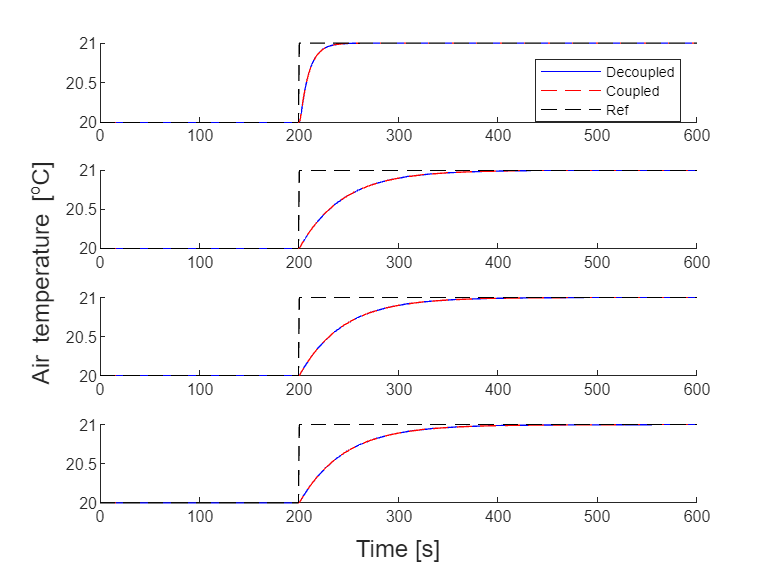

util.SimulateStep(param,"ExaminatinWightedDesignProedureStepMinGamma",0);

## Singular values when gamma is 1

The second synthesized controller is found while forcing gamma to be 1. 

param = control.DesignProcedureWeight(param,0,1);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0492    0.0496    0.0511    0.0519    0.1515    0.1524    0.1570    0.1585    0.5393    0.5393    0.5393    0.5393    1.1006    1.1015    1.1114    1.1127


Gamma is found to be:


ans = 1

Eigenvalues of the decoupled systems are all negative 


ans =   -4.2521 + 0.0000i  -0.2987 + 0.1886i  -0.2987 - 0.1886i  -4.3133 + 0.0000i  -0.3152 + 0.1995i  -0.3152 - 0.1995i  -4.2779 + 0.0000i  -0.3217 + 0.2003i  -0.3217 - 0.2003i  -4.2622 + 0.0000i  -0.3105 + 0.1861i  -0.3105 - 0.1861i


Eigenvalues of the coupled systems are all negative 


ans =    -4.5181   -4.6724   -4.7900   -4.8171   -0.9207   -1.0037   -1.0502   -0.6866   -0.3243   -0.2914   -0.2778   -0.2817


plotting the simulated repsonse of the coupled and decopiled to verify performance 

0.000000, 0.000000, 0.000000, -89.839659, 
-23.728742, 0.000000, -60.282624, -60.282624, 
0.000000, -0.279473, -0.279473, -0.279473, 


0.000000, 0.000000, -0.912699, -0.000000, 
0.000000, 0.000000, -1.070881, -0.000000, 


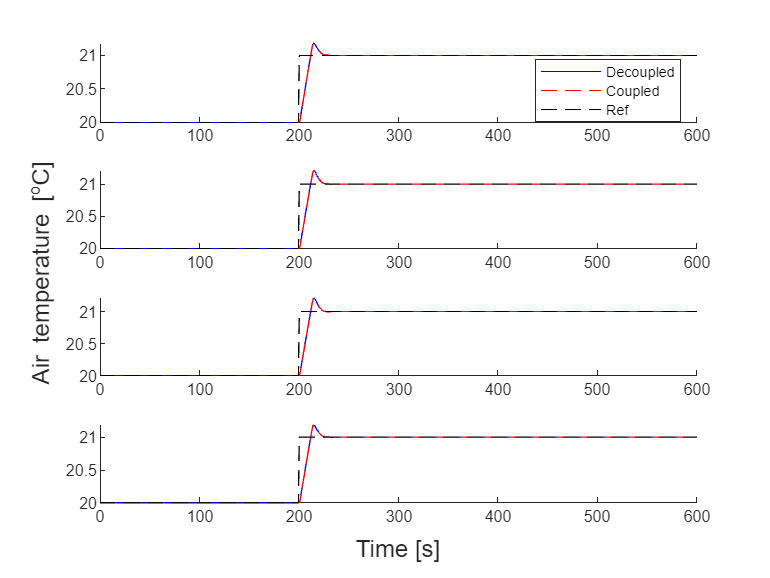

util.SimulateStep(param,"ExaminatinWightedDesignProedureStepGamma1",0);